# Dynamic Zero Policy for COVID-19

Weibin Gu, April 9, 2022

This live script models people's life under dynamic zero policy in the situation of COVID-19 in China. The idea is not coming from pandemics in a strict sense, but from the self-mockery of Chinese people as illustrated below.

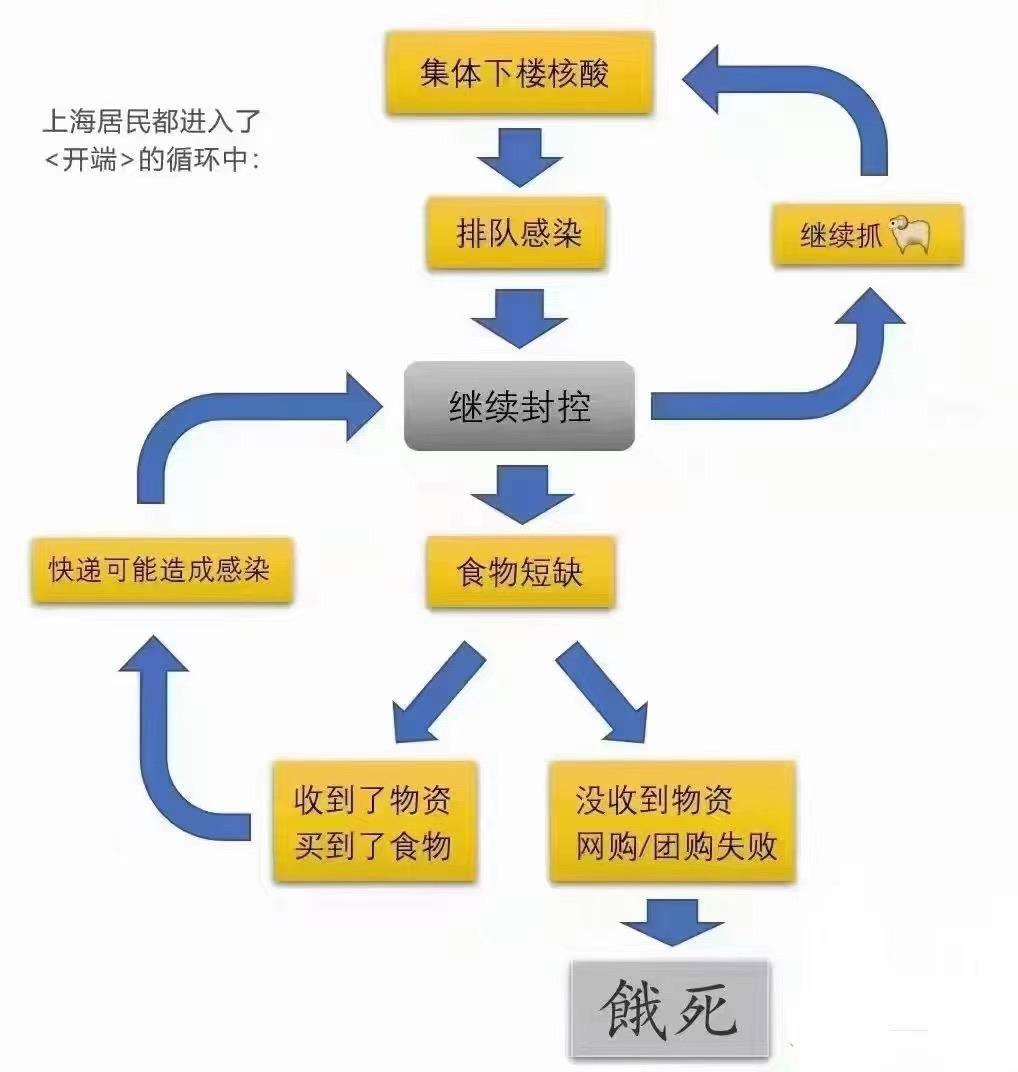

The code is self-explanatory and have quite a few parameters to play with. So far, it is only supported for MATLAB but can be easily implemented in other programming languages. Again, this is only a toy model that was developed for joyfulness. Feel free to make modifications or re-invent on top of this script and leave comments on mistakes or ways to improve. Thank you.

## Stamina

TODO: Classify people into the elder, baby, adult, and teenager.

S0 = 1; % initial condition 
%S = S0; % declared later
maximum_lifetime = 5% maximum lifetime under starving [day]

maximum_lifetime = 5

delta_S = 1/maximum_lifetime; % stamina loss per day [%]

## Food stock

$F$is the number of days that current food stock can support your life. At the end of each day, this will be reduced by 1 unless food stock is already empty.

Food consumption can be related to stamina loss by $\Delta F=\Delta S$ when food is sufficient (i.e., $F\ge 1$), and $\Delta F=F*\Delta S$ when $0\le F<1$. Of course, $\Delta F=0$ when $F=0$.

maximum_foodstock =7 % (initial condition) maximum food stock [day]

maximum_foodstock = 7

    % This is a critical variable affected by government annoucement, which
    % can be set as the anounced (expected) quarantined period.
%F = maximum_foodstock; % declared later

Amount of food delivery $F_d$, which will be directly added to food stock on its arrival: $F=F+F_d$. It is assumed that only one food delivery can be ordered at a time and the second can be only ordered when the first one is completed. This can be assumed if we can smooth the sequence of number of orders and then discretize it, from my imagination... 

food_delivery = 4% number of days that food delivery can support your life [day]

food_delivery = 4

Fd = food_delivery;

## Infection probability

COVID is powerful, and can be spread when you are in the queue to do nucleic acid test or even receiving deliveries (viruses are attached on the surface of the goods).

Pi_q = 5/100 % during nucleic acid test queue [%]

Pi_q = 0.0500

Pi_d = 1/100 % during receiving deliveries [%]

Pi_d = 0.0100

## Time interval of nucleic acid test and the arrival of deliveries

Basically, these are frequencies.

I also added randomness to food delivery frequency (in the final loop) to make things more interesting and realistic.

tq = 3 % (tq)-days per nucleic acid test

tq = 3

td = 7 % (td)-days per arrival of deliveries

td = 7


%td_rdm = round(td+randn(1)) % if you want to see the ideal case, delete
%randn(1)

## Let's roll the dice!

Stamina model: $S_{k+1} =S_k -\Delta S+\Delta F$, where $\Delta F$is defined previously.

Infection model: $p=p_{i,q} *T_q +p_{i,d} *T_d$, assuming two infections are independent, and $T_q ,T_d$ are "trigger parameters" which can be calculated by $T_i =\left(k\;\mathrm{mod}\;t_i \right)==0,i=\left\lbrace q,d\right\rbrace$for the ideal case. The following code also takes into account randomness of food delivery.

clear Tq Td P dice S F
S(1) = S0; % intialization
F(1) = maximum_foodstock; % intialization
td_ref = 0; % reference day to receive food delivery [day]
is_delivered = true; 

for k = 1:1000
    Tq(k) = mod(k,tq)==0;
    if is_delivered
        is_delivered = false;
        td_rdm = round(td+randn(1)); % random frequency of food delivery [day]
        td_ref = td_ref + td_rdm; % the day of food to be delivered [day]
    end
    if k == td_ref
        is_delivered = true;
        Td(k) = true;
    else
        Td(k) = false;
    end
    P(k) = Tq(k)*Pi_q + Td(k)*Pi_d; % infection model
    if Td(k)
        F(k+1) = F(k) + Fd; % food delivery
    else
        F(k+1) = F(k);
    end
    dice(k) = rand(1); % today's dice [%]
    if (dice(k) <= P(k))
        fprintf('You get infectious on Day %d.',k);
        break
    elseif (S(k) <= 0)
        fprintf('You starve to death on Day %d.',k);
        break
    else
        % Congratulations! You survived and started your day :)
        if F(k+1) >= 1
            refuel = (1-S(k))/delta_S; % refuel your stamina if it is not full [day]
            delta_F = delta_S * (1 + refuel);
        elseif F(k+1) >=0 && F(k+1) < 1
            delta_F = F(k+1)*delta_S; % start hungry
        else
            delta_F = 0; % woops, no food to eat
        end
        S(k+1) = S(k) - delta_S + delta_F; % stamina model
    end
    if F(k+1) > 0
        F(k+1) = F(k+1) - 1;
    else
        F(k+1) = F(k+1);
    end
end

You starve to death on Day 80.

## Let's look back over your life... (so sad)

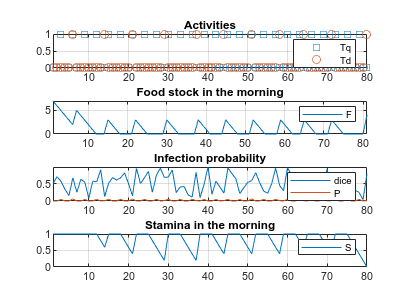

figure, 
subplot(4,1,1), plot(Tq,'s'), hold on, plot(Td,'o'), legend('Tq','Td'), grid on, axis tight, title('Activities')
subplot(4,1,2), plot(F), legend('F'), grid on, axis tight, title('Food stock in the morning')
subplot(4,1,3), plot(dice), hold on, plot(P), legend('dice','P'), grid on, axis tight, title('Infection probability')
subplot(4,1,4), plot(S), legend('S'), grid on, axis tight, title('Stamina in the morning')


fprintf("Conclusions: Assuming you can live without eating and drinking for %d days," + ...
    "and start quarantining with food stock of %d days. " + ...
    "You order food delivery every %d days," + ...
    "but finally your life ends on %d day, unfortunately.", ...
    maximum_lifetime, ...
    maximum_foodstock, ...
    food_delivery, ...
    k);

Conclusions: Assuming you can live without eating and drinking for 5 days,and start quarantining with food stock of 7 days. You order food delivery every 4 days,but finally your life ends on 80 day, unfortunately.

## Let's look at a big picture.

clear num_death num_inf num_day
num_death = 0; 
num_inf = 0;
num_day = 0; % survival day

% THE FOLLOWING IS THE SAME CODE WITH MINOR MODIFICATIONS
% AS SEEN IN 'ROLLING THE DICE'
for j = 1:100
    clear Tq Td P dice S F
    S(1) = S0; 
    F(1) = maximum_foodstock; 
    for k = 1:1000
        Tq(k) = mod(k,tq)==0;
        if is_delivered
            is_delivered = false;
            td_rdm = round(td+randn(1)); 
            td_ref = td_ref + td_rdm;
        end
        if k == td_ref
            is_delivered = true;
            Td(k) = true;
        else
            Td(k) = false;
        end
        P(k) = Tq(k)*Pi_q + Td(k)*Pi_d; 
        if Td(k)
            F(k+1) = F(k) + Fd; 
        else
            F(k+1) = F(k);
        end
        dice(k) = rand(1); 
        if (dice(k) <= P(k))
            num_inf = num_inf + 1; % accumulate
            break
        elseif (S(k) <= 0)
            num_death = num_death + 1; % accumulate
            break
        else
            if F(k+1) >= 1
                refuel = (1-S(k))/delta_S; 
                delta_F = delta_S * (1 + refuel);
            elseif F(k+1) >=0 && F(k+1) < 1
                delta_F = F(k+1)*delta_S; 
            else
                delta_F = 0; 
            end
            S(k+1) = S(k) - delta_S + delta_F; 
        end
        F(k+1) = F(k+1) - 1;
    end

    num_day = num_day + k; % accumulate
end

avg_inf = num_inf / j % probability of getting infectious

avg_inf = 0.1700

avg_death = num_death / j % probability of death

avg_death = 0.8300

avg_day = num_day / j

avg_day = 12.8500

fprintf("Running %d campaigns, " +...
    "it is found that getting infectious has probability %0.2f%%, " +...
    "and starving to death has probability %0.2f%%. " +...
    "The average normal day length is %0.2f.", ...
    j, ...
    avg_inf*100, ...
    avg_death*100, ...
    avg_day);

Running 100 campaigns, it is found that getting infectious has probability 17.00%, and starving to death has probability 83.00%. The average normal day length is 12.85.